Boat Project: Rowan and Jacob

%================Set up===============
%=====================================

width = 0.02*2;            % width  (m)
height = 0.06025;            % height (m)
boat_length = 0.07*2;            % length (m)

%plotting colors
blue = [0 162 255]./255;
black = [128 133 133]./255;
yellow = [255, 208, 0]./255;

% physical constants
wrho = 1000; % water density kg/m^3
g = 9.8;     % gravity m/s^2

dispratio = 0.4;    % ratio of boat displacement to max diplacement
CoM_offset = [0; 0;-0.005]; % Offset of the center of mass, e.g. using ballast


Npts = 100;                        % number of 1D spatial points (not a design variable; don't change)
xPoints = linspace(-width/2,width/2,Npts); % set of points in the x direction (horizontal)
yPoints = linspace(-boat_length/2,boat_length/2,Npts);
zPoints = linspace(0,height,Npts);      % set of points in the z direction (vertical)

[X, Y, Z] = meshgrid(xPoints,yPoints, zPoints); % create the meshgrid


global P insideBoat dV boatdisp wrho
P = [X(:)'; Y(:)'; Z(:)']; 

a = [];
insideBoat = zeros(size(P(1,:)));


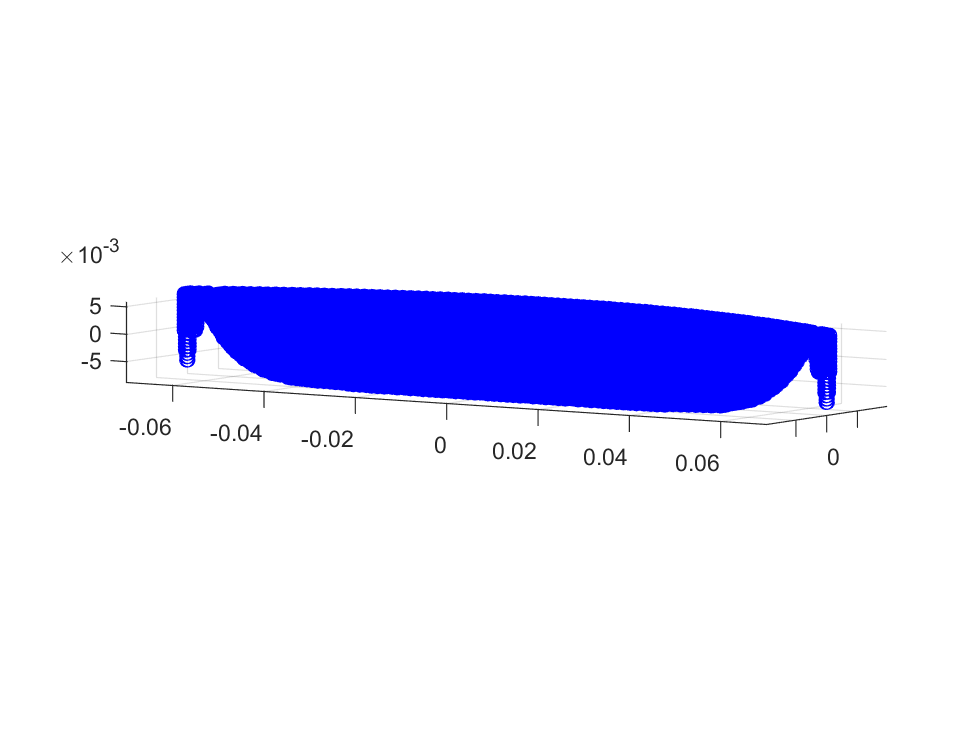

%===================Define Boat (carve boat out of block)=======
%===============================================================

for i = 1:1:Npts
    %get the height of the parabola section using sheer plane equation for
    %current "slice" / section of boat
    sheer_plane_height = sheer_plane_function(P(2,i));
    %get the width of the parabola section
    water_plane_width = hull_plane_function(P(2,i));
    %compute parabola "A" term
    ellipse_width = water_plane_width;
    ellipse_height = height - sheer_plane_height;
    
    %y = a(x-h)^2+k
    
    insideSlice = (P(2,:) == yPoints(i));
    
    t2 = (ellipse_height^2);
    t1 = -(t2) .* (P(1,:).^2);
    t3 = (ellipse_width^2);
    
    Z_bottom = -1 * sqrt((t1/t3) + t2) + height;
    
    %Z_bottom = parabola_width.*(P(1,:)).^2 + sheer_plane_height;
    Z_top = height;
    
    
    insideSection = (P(3,:) > Z_bottom) & (P(3,:) < Z_top);
    %scatter3(P(1,insideSection&insideSlice), P(2,insideSection&insideSlice), P(3,insideSection&insideSlice), ".k");
    insideBoat = insideBoat + (insideSection&insideSlice);
    

    

    
end
%take care of any overlap by constraining between 0 and 1

insideBoat = insideBoat > 0;

dx = xPoints(2)-xPoints(1); % delta x
dy = yPoints(2)-yPoints(1); % delta y
dz = zPoints(2)-zPoints(1); % delta z
dV= dx*dz*dy;

boatmasses = transpose(insideBoat)*wrho*dV;% find the water mass of each small section

maxdisp = sum(boatmasses);        % find the maximum displacement of the boat
boatdisp = dispratio*maxdisp ;    % set the displacement of the boat
CoD = P*boatmasses/maxdisp ;      % find the centroid of the boat consider inside boat????
P = P - CoD;                       % center the boat on the centroid
CoD = CoD - CoD;                   % update the centroid after centering
CoM = CoD + CoM_offset    ;     % adjust the center of mass, e.g. for ballast


%3D view
clf
scatter3(P(1,insideBoat), P(2,insideBoat), P(3,insideBoat), 'b')
axis equal

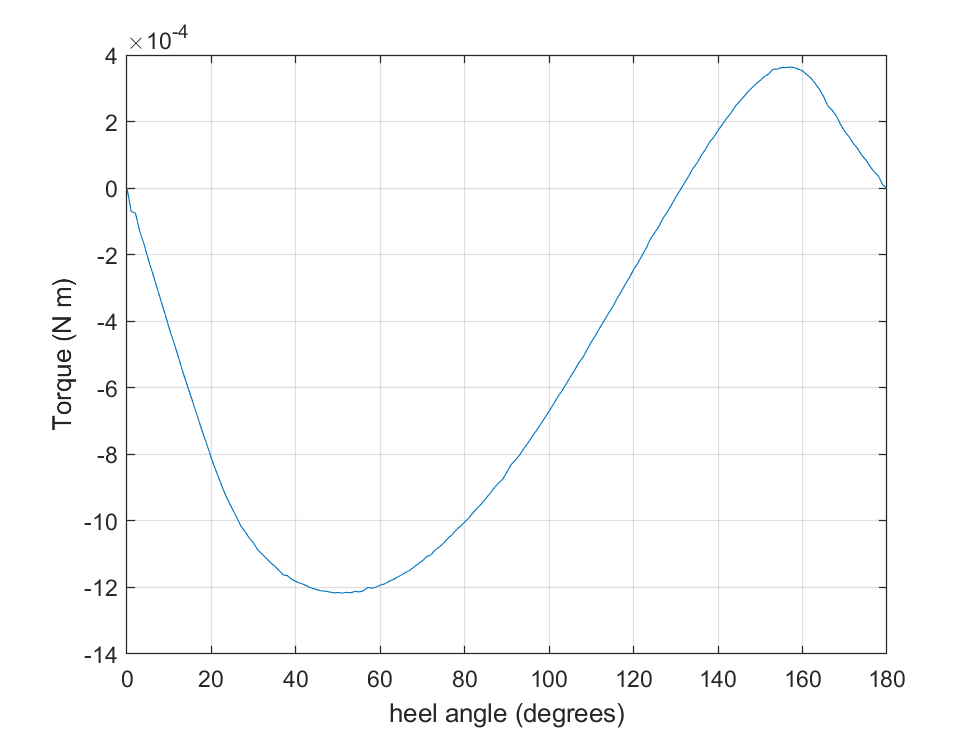

%======================torque curve calculation=====================
%===================================================================

dtheta = 1; % define the angle step
R = [cosd(dtheta) 0 -sind(dtheta);
  0 1 0;
  sind(dtheta) 0 cosd(dtheta)];
theta_list = 0:dtheta:180;
torque = zeros(length(theta_list));
angle = zeros(length(theta_list));

P_analysis = P;
PCoM = CoM;

 % set the counter
for j =1:length(theta_list)% loop over the angles
    % Bound the waterline
    dmin = min(P_analysis(3, :)); % find the minimum z coordinate of the boat
    dmax = max(P_analysis(3, :)); % find the maximum z coordinate of the boat
    % Solve for the waterline of the rotated boat
    d = fzero(@waterline_error, [dmin, dmax]); % find the waterline d
% Analyze the boat
    underWater = (P_analysis(3,:) <= d)';
    underWaterAndInsideBoat = insideBoat & underWater';
    watermasses = underWaterAndInsideBoat*wrho*dV;
    watermass = sum(watermasses);
    CoB = P_analysis*watermasses'./watermass';
    % Store the results
    torque(j) = boatdisp * g * (CoB(1) - PCoM(1)); % find the torque (N m)
    
%     if CoB(3) > PCoM(3)
%         torque(j) = torque(j) * 1;
%     end
    angle(j) = theta_list(j);                                 % record the angle (deg)


    % Rotate the system
    P_analysis = R*P_analysis;     % rotate the boat by dtheta
    PCoM = R*PCoM; % rotate the center of mass too
end

clf
plot(angle, torque)
xlabel('heel angle (degrees)')
ylabel('Torque (N m)')
grid on

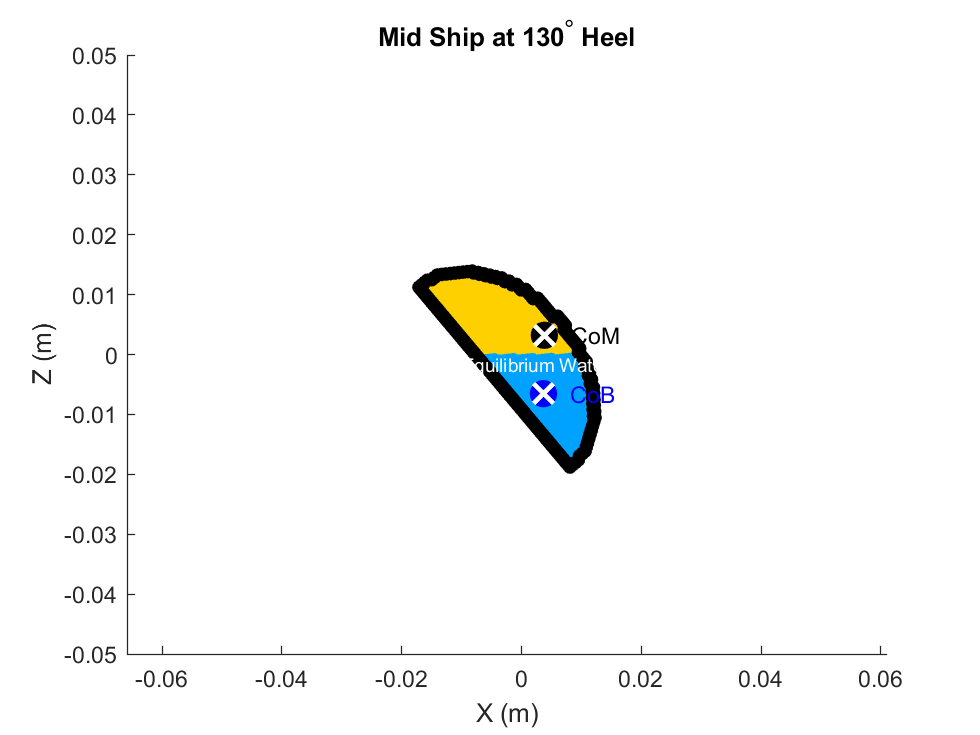

%===================Mid-Ship plot at any heel angle===================
%=====================================================================
theta = 130; % define the angle step
R = [cosd(theta) 0 -sind(theta);
  0 1 0;
  sind(theta) 0 cosd(theta)];


 % set the counter
    P_analysis = R*P;     % rotate the boat by dtheta
    PCoM = R*CoM; % rotate the center of mass too
    % Bound the waterline
    dmin = min(P_analysis(3, :)); % find the minimum z coordinate of the boat
    dmax = max(P_analysis(3, :)); % find the maximum z coordinate of the boat
    % Solve for the waterline of the rotated boat
    d = fzero(@waterline_error, [dmin, dmax]); % find the waterline d
% Analyze the boat
    underWater = (P_analysis(3,:) <= d)';
    underWaterAndInsideBoat = insideBoat & underWater';
    watermasses = underWaterAndInsideBoat*wrho*dV;
    watermass = sum(watermasses);
    PCoB = P_analysis*watermasses'./watermass';
                            % record the angle (deg)


%code to find the bondaries for fancy plotting
insideSlice = P_analysis(2,:) == P_analysis(2,int16(Npts/2));
slice = insideSlice & insideBoat;
border  = zeros(size(slice));
for i = Npts^2+1:length(slice) - Npts^2-1
    
    if (slice(i) == true && (slice(i+Npts) == false || slice(i-Npts) == false || slice(i-Npts^2) == false || slice(i+Npts^2) == false))
            border(i) = 1;
    end
end
border = border == 1;


%plot
clf
hold on


plot(P_analysis(1,insideBoat & insideSlice), P_analysis(3,insideBoat & insideSlice), '.', 'MarkerSize', 20, "Color", yellow)
plot(P_analysis(1,underWaterAndInsideBoat & insideSlice), P_analysis(3,underWaterAndInsideBoat & insideSlice), '.', "Markersize", 20, "Color", blue)


plot(PCoM(1), PCoM(3), 'k.', "Markersize", 40)
plot(PCoM(1), PCoM(3), 'wx', "Markersize", 12, "Linewidth", 2)
plot(PCoB(1), PCoB(3), 'b.', "Markersize", 40)
plot(PCoB(1), PCoB(3), 'wx', "Markersize", 12, "Linewidth", 2)

plot(P_analysis(1,border), P_analysis(3,border), 'k.', 'MarkerSize', 20)

text(PCoM(1)-0.002,PCoM(3),'      CoM','FontSize',10,'Color','k')
text(PCoB(1)-0.002,PCoB(3),'      CoB','FontSize',10,'Color','b')
text(-.01, d-0.001,'Equilibrium Water Line','FontSize',8,'Color','w')

ylim([-0.05 0.05]);
xlabel("X (m)")
ylabel("Z (m)")
title("Mid Ship at " + string(theta) + "^\circ Heel")
axis equal
hold off


PCoB

PCoB =     0.0037
   -0.0000
   -0.0065


PCoM

PCoM =     0.0038
         0
    0.0032


function res = sheer_plane_function(x)
res = zeros(size(x));
res = (1E10 .* x .^ 10) + 0.045;
%      if x < -0.04185 || x > 0.04185
%          res = res + (1E10 .* x .^ 10) + 0.032;
%      end
%      if x >= -0.04185 && x <= 0.04185
%          res = res + ((-1 * ((0.037^3.5) / (x.^2 + 0.037^(2.5)))) + 0.037);
%      end  
end

%fucntion for width of boat as viewd from above
function res = hull_plane_function(x)
res = -3.83*(x^2) + 0.02;
end

function res = waterline_error(d)
global P insideBoat dV boatdisp wrho

    underWater = (P(3,:) <= d)'; % test if each part of the meshgrid is under the water
    watermass = sum(underWater' & insideBoat) .* dV * wrho;
    res = watermass - boatdisp; % difference between boat displacement and water displacement
end
